# 1. Transferring a robot

## 1.0 Initialization

clear;

## 1.1 The setup

% Given dynamics matrices 
A = [1  0   0.1   0;...
     0  1   0     0.1;...
     0  0   0.9   0;...
     0  0   0     0.9];
B = [0   0;...
     0   0;...
     0.1 0;...
     0   0.1];
n = 4;
m = 2; 

## 1.2 The $l_2^2$ regularizer

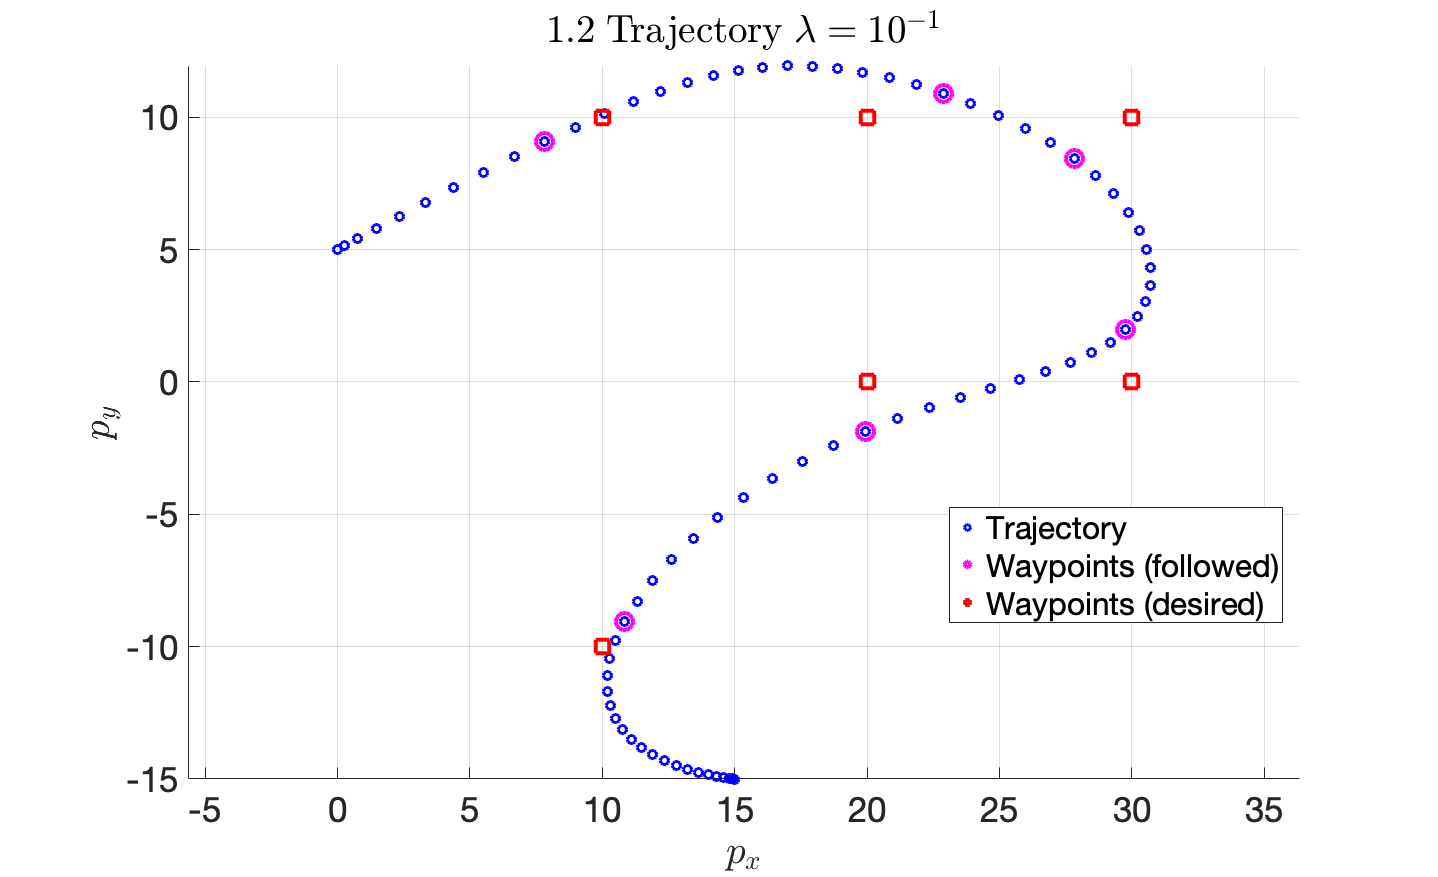

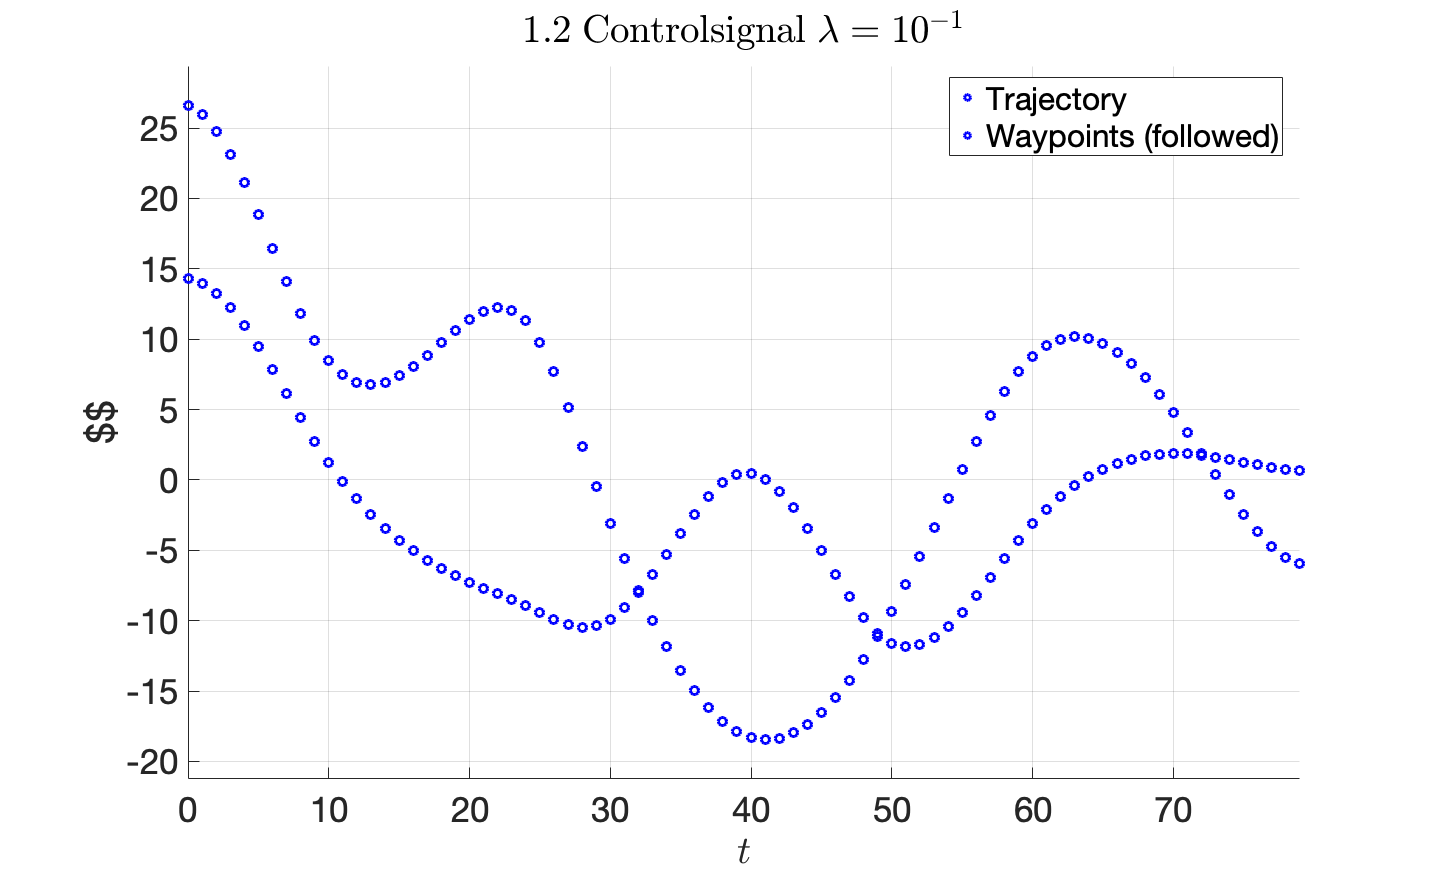

For lambda = 1e-1 there were 79 optimal control signal changes.


For lambda = 1e-1 the mean deviation from the waypoints is 2.195805.


% Given parameters
T = 80;
p_initial = [0;5];
p_final = [15;-15];
w = [10 10; 20 10; 30 10; 30 0; 20 0; 10 -10]';
tau = [10 25 30 40 50 60];
U_max = 100;
E = [eye(2) zeros(2)];

controlSignalChanges = [];
meanDeviation = [];

for lambda_log = -1%-3:3
    % ---------- Setup optimization problem ----------
    cvx_begin quiet
        % optimization variables
        variables x(n,T+1) u(m,T)
        % cost function
        minimize(sum(sum_square(E*x(:,tau+1)-w))+...
            (10^lambda_log)*sum(sum_square(u*(diag(-[ones(T-1,1);0])+diag(ones(T-1,1),-1)))));
        % subject to
        x(:,1) == [p_initial;zeros(2,1)];
        x(:,end) == [p_final;zeros(2,1)];
        for t = 1:T
            x(:,t+1) == A*x(:,t)+B*u(:,t);
            norm(u(:,t)) <= U_max;
        end
    cvx_end
    
    % ---------- Plot result ----------
    % trajectory
    figure('units','normalized','outerposition',[0 0 1 1]);
    hold on;
    set(gca,'FontSize',35);
    ax = gca;
    ax.XGrid = 'on';
    ax.YGrid = 'on';
    axis equal;
    title(strcat('$1.2\;a)\; \mathrm{Trajectory}\;\lambda =',sprintf('10^{%d}$',lambda_log)),'Interpreter','latex');
    scatter(x(1,:),x(2,:),70,'o','blue','LineWidth',3);
    scatter(x(1,tau+1),x(2,tau+1),300,'o','magenta','LineWidth',4);
    scatter(w(1,:),w(2,:),300,'s','red','LineWidth',4);
    legend('Trajectory','Waypoints (followed)', 'Waypoints (desired)','Location','best');
    ylabel('$p_y$','Interpreter','latex');
    xlabel('$p_x$','Interpreter','latex');
    saveas(gcf,sprintf('./transferring_a_robot_data/1_2_trajectory_lambdalog_%d.fig',lambda_log));
    saveas(gcf,sprintf('./transferring_a_robot_data/1_2_trajectory_lambdalog_%d.png',lambda_log));
    hold off; 
    
    % control signal
    figure('units','normalized','outerposition',[0 0 1 1]);
    hold on;
    set(gca,'FontSize',35);
    ax = gca;
    ax.XGrid = 'on';
    ax.YGrid = 'on';
    axis equal;
    title(strcat('$1.2\;b)\; \mathrm{Control signal}\;\lambda =',sprintf('10^{%d}$',lambda_log)),'Interpreter','latex');
    scatter(0:T-1,u(1,:),70,'o','blue','LineWidth',3);
    scatter(0:T-1,u(2,:),70,'o','blue','LineWidth',3);
    legend('$\mathbf{u}_1$','$\mathbf{u}_2$','Location','best','interpreter','latex');
    ylabel('$ $','Interpreter','latex');
    xlabel('$t$','Interpreter','latex');
    saveas(gcf,sprintf('./transferring_a_robot_data/1_2_controlSignal_lambdalog_%d.fig',lambda_log));
    saveas(gcf,sprintf('./transferring_a_robot_data/1_2_controlSignal_lambdalog_%d.png',lambda_log));
    hold off;
    
    controlSignalChangesCur = 0;
    for t = 1:T-1
        if norm(u(t+1)-u(t))>1e-6
            controlSignalChangesCur = controlSignalChangesCur+1;
        end
    end
    controlSignalChanges = [controlSignalChanges [10^lambda_log;controlSignalChangesCur]]; 
    fprintf("1.2 c) For lambda = 1e%d there were %d optimal control signal changes.\n",lambda_log,controlSignalChangesCur);
    
    meanDeviationCur = (1/length(w))*sum(sqrt(sum_square(E*x(:,tau+1)-w)));
    meanDeviation = [meanDeviation [10^lambda_log; meanDeviationCur]];
    fprintf("1.2 d) For lambda = 1e%d the mean deviation from the waypoints is %f.\n",lambda_log,meanDeviationCur);
end

save('./transferring_a_robot_data/1_2_data_c_d.fig','controlSignalChanges','meanDeviation');
